# Rigid Body Double Pendulum - n-t and x-y coordinates

## Problem Statement

Determine the EOMs of the Rigid Body Double Pendulum. Use equal mass, length, and mass moment of inertia for both bars. Use $\theta$ and $\phi$ as your DOFs, with a *n-t *coordinate system for bar 1 and a *x-y *coordinate system for bar 2. After determining constraints, the result should be 8 equations and 8 unknowns. I recommend using the Matlab Symbolic Toolbox to solve the system of equations for the 2 EOMs.

        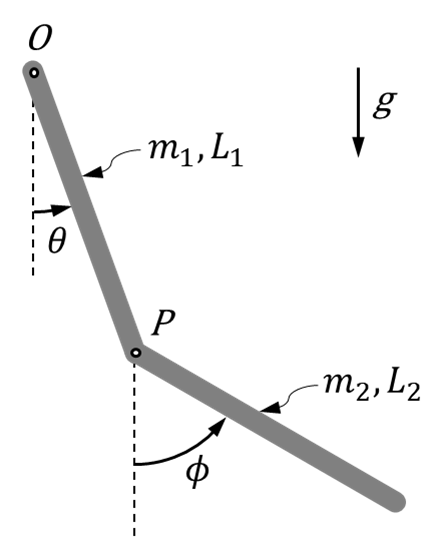

## Step 1: Conceptualize The Problem

Find the angular displacements as functions of time by determining the EOMs and numerically integrating them using ode45.

- 2 degrees of freedom, $\theta$ and $\phi$

- Gravity is acting

- Masses move without any friction or drag

- Equal masses, equal lengths

- Treat as rigid bodies

- Assume initial conditions can be specified (want to study various IC's)

## Step 2: Coordinate System

A normal-tangential coordinate system is used for bar 1. A Cartesian system is used for bar 2. Constraint equations will be used to relate the Cartesian components to the angles.

## Step 3: Free-Body Diagram

Individual FBDs for bars 1 and 2.

        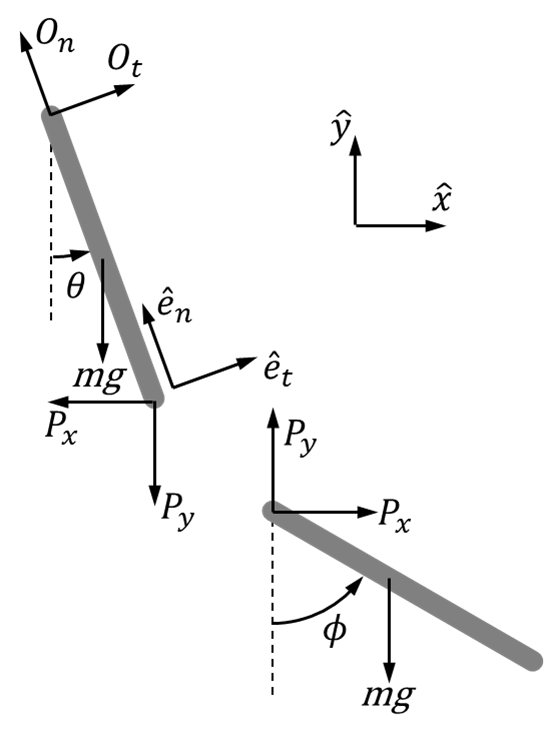

## Step 4: Fundamental Equations

The EOMs are derived starting with Newton's second law


$$\bar{F}=m\bar{a}$$


Details are in the appendix.

clear
syms m L theta theta_dot phi phi_dot g
syms On Ot Px Py x_ddot y_ddot theta_ddot phi_ddot

eqn(1) = m*(L/2*theta_dot^2) == On-m*g*cos(theta)+Px*sin(theta)-Py*cos(theta);
eqn(2) = m*(L/2*theta_ddot) == Ot-m*g*sin(theta)-Px*cos(theta)-Py*sin(theta);
eqn(3) = (1/3*m*L^2)*theta_ddot == -m*g*L/2*sin(theta)-Px*L*cos(theta)-Py*L*sin(theta);

eqn(4) = m*x_ddot == Px;
eqn(5) = m*y_ddot == Py-m*g;
eqn(6) = (1/12*m*L^2)*phi_ddot == -Px*L/2*cos(phi)-Py*L/2*sin(phi);

## Step 5: Knowns and Unknowns

### Knowns


$$m, g, L, I$$


### Unknowns


$$\ddot{\theta}, \ddot{\phi}, \ddot{x}_2, \ddot{y}_2, O_n, O_t, P_x, P_y$$


## Step 6: Constraints

Constraints between acceleration components.

eqn(7:8) = [x_ddot,y_ddot] == L*theta_ddot*[cos(theta),sin(theta)]+L*theta_dot^2*[-sin(theta),cos(theta)]+...
    L/2*phi_ddot*[cos(phi),sin(phi)]+L/2*phi_dot^2*[-sin(phi),cos(phi)];

Now have 8 eqs and 8 unknowns.

## Step 7: Obtain the EOMs

unknowns = solve(eqn,[On,Ot,Px,Py,x_ddot,y_ddot,theta_ddot,phi_ddot]);
tdd = simplify(unknowns.theta_ddot)

$$tdd = -\frac{12\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\varphi }}^{2}+9\,L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\theta }}^{2}+9\,g\,\sin\left(2\,\varphi -\theta \right)-27\,g\,\sin\left(\theta \right)}{L\,\left(9\,\cos\left(2\,\varphi -2\,\theta \right)-23\right)}$$

pdd = simplify(unknowns.phi_ddot)

$$pdd = \frac{9\,L\,\sin\left(2\,\varphi -2\,\theta \right)\,{\dot{\varphi }}^{2}+48\,L\,\sin\left(\varphi -\theta \right)\,{\dot{\theta }}^{2}+21\,g\,\sin\left(\varphi \right)+27\,g\,\sin\left(\varphi -2\,\theta \right)}{L\,\left(9\,\cos\left(2\,\varphi -2\,\theta \right)-23\right)}$$

## Step 8: Solve the EOMs

### Solve nonlinear EOMs

Make all state variables symbolic functions of time

syms theta(t) theta_dot(t) phi(t) phi_dot(t)

Substitute these symbolic functions into the EOMs. Then have Matlab produce the eom sub-function using the odeFunction command. The 3 sets of arguments passed to odeFunction are the expressions for the derivatives of the state variables, the state variables, and then any other parameters that appear in the derivative expressions. Note that the order of the state variables and their derivatives is arbitrary but must be consistent.

accelEOMs = subs([unknowns.theta_ddot;unknowns.phi_ddot],...
    [str2sym('theta'),str2sym('theta_dot'),str2sym('phi'),str2sym('phi_dot')],...
    [theta,theta_dot,phi,phi_dot]);
eom = odeFunction([theta_dot;phi_dot;accelEOMs],[theta;phi;theta_dot;phi_dot],g,L);

Specify parameter values and integrate EOMs. Order of IC's must match state variables in odeFunction call.

Ln = 1.5*0.3048; % ft-to-m
gn = 9.81; % m/s^2
theta0 = pi/6; % rad
phi0 = pi/3; % rad
[T,S] = ode45(@(t,s)eom(t,s,gn,Ln),linspace(0,10,301),[theta0,phi0,0,0]);

Plot time history of angles

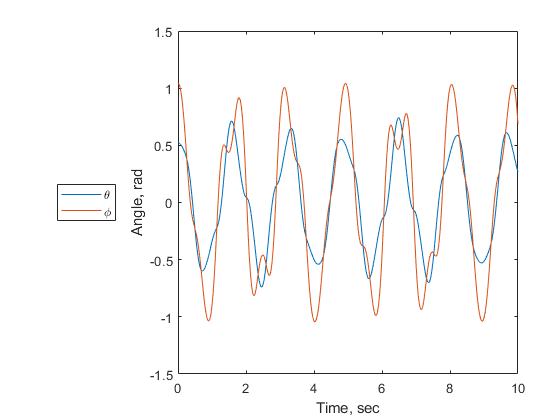

plot(T,S(:,1:2))
xlabel('Time, sec')
ylabel('Angle, rad')
legend('\theta','\phi','Location','WestOutside')

Plot animation of motion:

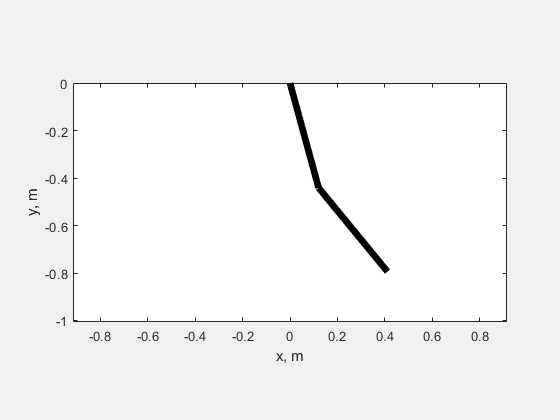

ax1 = Ln*sin(S(:,1));
ay1 = -Ln*cos(S(:,1));
ax2 = Ln*(sin(S(:,1))+sin(S(:,2)));
ay2 = -Ln*(cos(S(:,1))+cos(S(:,2)));
figure("Visible","on")
h = plot([0,ax1(1)],[0,ay1(1)],'-k',[ax1(1),ax2(1)],[ay1(1),ay2(1)],...
    '-k','LineWidth',5);
xlabel('x, m')
ylabel('y, m')
axis equal
ylim([-2*Ln*1.1,0])
xlim([-2*Ln,2*Ln])
for i = 2:length(ax1)
    set(h(1),'XData',[0,ax1(i)],'YData',[0,ay1(i)]);
    set(h(2),'XData',[ax1(i),ax2(i)],'YData',[ay1(i),ay2(i)]);
    drawnow
    pause(1/30);
end

## Step 9: Does It Make Sense?

### Units:

Check Equations

u = symunit;
Variables.m = m*u.kg;
Variables.g = g*u.m/u.s^2;
Variables.L = L*u.m;
Variables.On = On*u.N;
Variables.Ot = Ot*u.N;
Variables.Px = Px*u.N;
Variables.Py = Py*u.N;
Variables.x_ddot = x_ddot*u.m/u.s^2;
Variables.y_ddot = y_ddot*u.m/u.s^2;
Variables.theta_dot = theta_dot/u.s;
Variables.phi_dot = phi_dot/u.s;
Variables.theta_ddot = theta_ddot/u.s^2;
Variables.phi_ddot = phi_ddot/u.s^2;
eqnUnits = subs(eqn,Variables);
checkUnits(eqnUnits)

ans = struct with fields:
    Consistent: [1 1 1 1 1 1 1 1]
    Compatible: [1 1 1 1 1 1 1 1]


All equations have consistent and compatible units

Check EOMs

theta_ddotEOMUnits = subs(tdd,Variables);
[~,thetaEOMUnits] = separateUnits(theta_ddotEOMUnits);
thetaEOMUnits

$$thetaEOMUnits = \frac{1}{s^{2}}$$

Confirms that $\ddot{\theta}$ is in $\text{rad/s}^2$

phi_ddotEOMUnits = subs(pdd,Variables);
[~,phiEOMUnits] = separateUnits(phi_ddotEOMUnits);
phiEOMUnits

$$phiEOMUnits = \frac{1}{s^{2}}$$

Confirms that $\ddot{\phi}$ is in $\text{rad/s}^2$

### Magnitudes and Signs

In this work, the magnitude and signs are confirmed with the animation showing that the output looks physically reasonable. The magnitude of the oscillations are not growing or decaying, consistent with our assumptions of no losses. The signs can be further tested and confirmed by trying different initial conditions with both positive and negative initial angles.

## Appendix

### Contributions

who did what...

### Attachments

EOMs derived during class lecture.